# Comparison between EMS

## Get current folder and add all folders below Projet-1 to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ~strcmp(currentfolder{end}, 'Projet-1')
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath))

## Get the data

folder_data = strcat(projectpath,'\Data\');

## File

PI.out = outPI;
SMC.out = outSMC;
FUZZY.out = outFUZZY;

% tic
% PI = load(strcat(folder_data,'PI_300.mat'));
% SMC = load(strcat(folder_data,'SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B20_PI_300.mat'));
% SMC = load(strcat(folder_data,'B20_SMC_300.mat'));
% FUZZY = load(strcat(folder_data,'B20_FUZZY_300.mat'));
% toc

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% toc

## Voltage curve

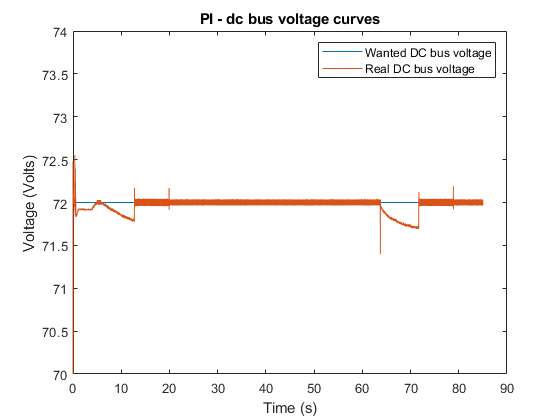

tic
bus_curve(PI,'PI');

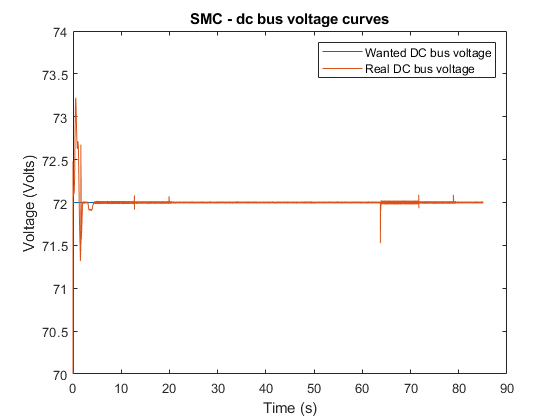

bus_curve(SMC,'SMC');

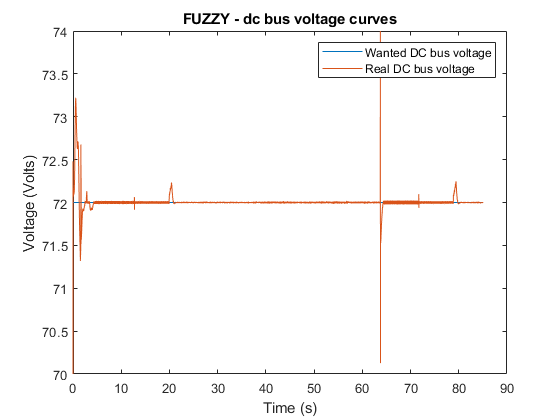

bus_curve(FUZZY,'FUZZY');

toc

Elapsed time is 8.768675 seconds.


## Power curve

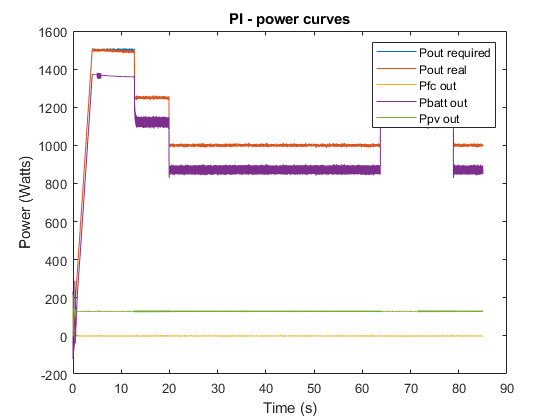

tic
power_curve(PI,'PI');

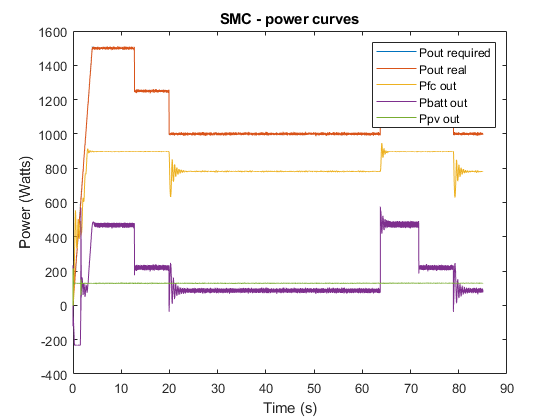

power_curve(SMC,'SMC');

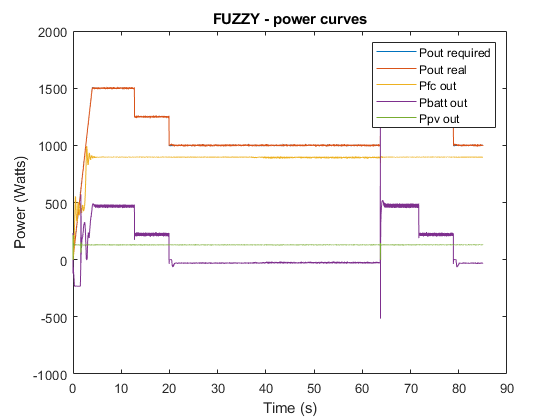

power_curve(FUZZY,'FUZZY');

toc

Elapsed time is 13.118348 seconds.


# Comparison data

## Power mean value

tic
[P_FC_in_PI, P_PV_in_PI, P_batt_in_PI, P_SC_PI] = mean_power_sim(PI,'in');
[P_FC_in_SMC, P_PV_in_SMC, P_batt_in_SMC, P_SC_SMC] = mean_power_sim(SMC,'in');
[P_FC_in_FUZZY, P_PV_in_FUZZY, P_batt_in_FUZZY, P_SC_FUZZY] = mean_power_sim(FUZZY,'in');
[P_FC_out_PI, P_PV_out_PI, P_batt_out_PI, P_SC_PI] = mean_power_sim(PI,'out');
[P_FC_out_SMC, P_PV_out_SMC, P_batt_out_SMC, P_SC_SMC] = mean_power_sim(SMC,'out');
[P_FC_out_FUZZY, P_PV_out_FUZZY, P_batt_out_FUZZY, P_SC_FUZZY] = mean_power_sim(FUZZY,'out');


col1 = [P_FC_in_PI; P_FC_out_PI ; P_PV_in_PI; P_PV_out_PI; P_batt_in_PI; P_batt_out_PI; P_SC_PI];
col2 = [P_FC_in_SMC; P_FC_out_SMC; P_PV_in_SMC; P_PV_out_SMC; P_batt_in_SMC; P_batt_out_SMC; P_SC_SMC];
col3 = [P_FC_in_FUZZY; P_FC_out_FUZZY; P_PV_in_FUZZY; P_PV_out_FUZZY; P_batt_in_FUZZY; P_batt_out_FUZZY; P_SC_FUZZY];
row_names = {'Pfc_in','Pfc_out','Ppv_in','Ppv_out','Pbatt_in','Pbatt_out','Psc'};
column_names = {'PI','SMC','FUZZY'};
table(col1,col2,col3,'RowNames',row_names,'VariableNames',column_names)

ans = 7×3 table
                    PI        SMC      FUZZY 
                 ________    ______    ______

    Pfc_in       0.061066    907.38     981.6
    Pfc_out      -0.98989    814.24    880.68
    Ppv_in         144.53     144.8    144.72
    Ppv_out        129.01    129.24    129.17
    Pbatt_in       1109.7    203.37    132.98
    Pbatt_out      998.24     182.3    115.88
    Psc            1.3437    3.1515    3.2257


toc

Elapsed time is 6.004185 seconds.


## Error mean value

tic
[rmse_p_PI,rmse_v_PI,mep_PI, mev_PI] = error_sim(PI);
[rmse_p_SMC,rmse_v_SMC,mep_SMC, mev_SMC] = error_sim(SMC);
[rmse_p_FUZZY,rmse_v_FUZZY,mep_FUZZY, mev_FUZZY] = error_sim(FUZZY);

col11 = [rmse_p_PI;rmse_v_PI;mep_PI; mev_PI];
col22 = [rmse_p_SMC;rmse_v_SMC;mep_SMC; mev_SMC];
col33 = [rmse_p_FUZZY;rmse_v_FUZZY;mep_FUZZY; mev_FUZZY];
row_names = {'RMSE P','RMSE V','MEP','MEV'};
column_names = {'PI','SMC','FUZZY'};
table(col11,col22,col33,'RowNames',row_names,'VariableNames',column_names)

ans = 4×3 table
                 PI         SMC        FUZZY  
              ________    ________    ________

    RMSE P      3.3854     0.97706      1.6629
    RMSE V    0.084046    0.091788    0.098808
    MEP        0.13392    0.052518    0.061046
    MEV       0.067024    0.026204    0.030468


toc

Elapsed time is 3.075459 seconds.


## Consumption

tic
[chydro_PI, Batt_SOC_PI, Batt_SOH_PI,age_PI] = consumption_sim(PI);
[chydro_SMC, Batt_SOC_SMC, Batt_SOH_SMC,age_SMC] = consumption_sim(SMC);
[chydro_FUZZY, Batt_SOC_FUZZY, Batt_SOH_FUZZY,age_FUZZY] = consumption_sim(FUZZY);

col111 = [chydro_PI; Batt_SOC_PI; Batt_SOH_PI;age_PI];
col222 = [chydro_SMC; Batt_SOC_SMC; Batt_SOH_SMC; age_SMC];
col333 = [chydro_FUZZY; Batt_SOC_FUZZY; Batt_SOH_FUZZY; age_FUZZY];

row_names = {'H2 cons','SOC','SOH','age'};
column_names = {'PI','SMC','FUZZY'};
table(col111,col222,col333,'RowNames',row_names,'VariableNames',column_names)

ans = 4×3 table
                   PI          SMC       FUZZY 
               __________    _______    _______

    H2 cons    8.0714e-05     1.1926     1.3476
    SOC            81.551      84.38     84.594
    SOH           0.96551     0.9938    0.99594
    age                 1    0.99905    0.99917


toc

Elapsed time is 0.488433 seconds.
